# Course: Image Processing and Pattern Recognition Lab

Sem: WS20/21

Date: 28.11.2020

Group Id: Carl Friedrich Gauß

Group Members:

1. Prashasti Sahu

2. Friedrich Mütschele

Description: This MATLAB file contains the code implemented as part of LAB 1 - Exercise 02

**Task 1** Load all the four test images and convert them to grey scale. 

Note: use the variable naming convention as show in in below

% Implement your code here
test_img01_original=imread("test_img 01.jpg");
test_img02_original=imread("test_img 02.jpg");
test_img03_original=imread("test_img 03.jpg");
test_img04_original=imread("test_img 04.jpg");
test_img01_grey=rgb2gray(test_img01_original);
test_img02_grey=rgb2gray(test_img02_original);
test_img03_grey=rgb2gray(test_img03_original);
test_img04_grey=rgb2gray(test_img04_original);

**Task 2** Plot the histogram for test_img 01 and test_img 02 grey scale images and label and title the figures accordingly. Hint: You can use the MATLAB's inbuilt histogram function for an Image

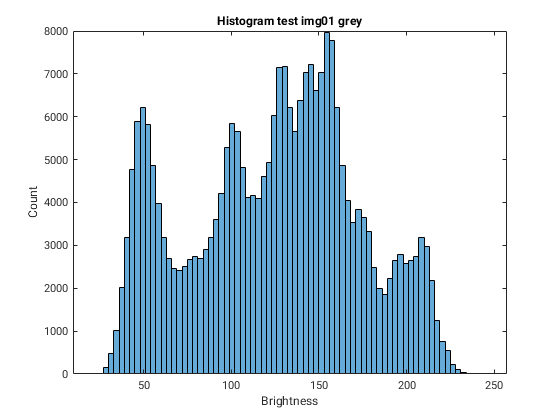

% Implement your code here
histogram(test_img01_grey)
xlabel('Brightness')
ylabel('Count')
title('Histogram test img01 grey')

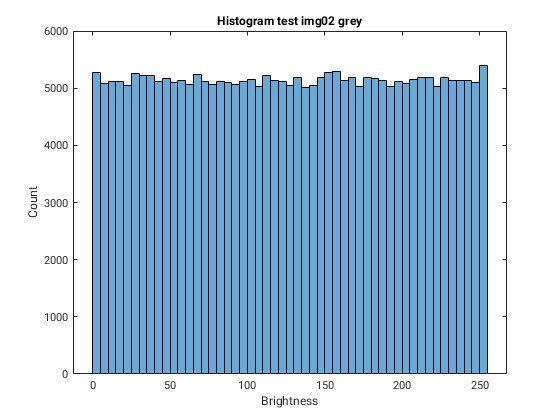

histogram(test_img02_grey)
xlabel('Brightness')
ylabel('Count')
title('Histogram test img02 grey')

**Task 3** Compute the mean and variance manually for test_img 01 and test_img 02 grey sclae images. Don't use the MATLAB inbuilt functions for mean and variance calculation.

%for reference
%matlab_mean = mean(test_img01_grey(:))
%matlab_var = var(double(test_img01_grey(:)))

[rows, cols, ch] = size(test_img01_grey);
mean_img01_gray = 1/(rows*cols) * sum(test_img01_grey(:))

mean_img01_gray = 124.1148

var_img01_gray = 1/(rows*cols) * sum((double(test_img01_grey(:))-mean_img01_gray).^2)

var_img01_gray = 2.2989e+03


%for reference
%matlab_mean = mean(test_img02_grey(:))
%matlab_var = var(double(test_img02_grey(:)))

[rows, cols, ch] = size(test_img01_grey);
mean_img02_gray = 1/(rows*cols) * sum(test_img02_grey(:))

mean_img02_gray = 127.0604

var_img02_gray = 1/(rows*cols) * sum((double(test_img02_grey(:))-mean_img01_gray).^2)

var_img02_gray = 5.4472e+03

Describe your observations:

for test_img 01: Mean is relatively centric, variance is already high 

mean, variance: `124.1148, 2.2989e+03`

for test_img 02: Mean is in the center, variance is even higher (uniform distribution here)

mean, variance: `127.0604, 5.4472e+03`

**Task 4** Implement a point operation f(x) = a*(x)+b on images test_img 01 and test_img 02 greyscale images. Store the resultant images after point operation to variables **test_img01_point_oper**, **test_img02_point_oper**. Plot the histogram of the resultant images.

% Implement your code here. use the below slider values as part of your
% code
a =1.3

a = 1.3000

b = 0

b = 0

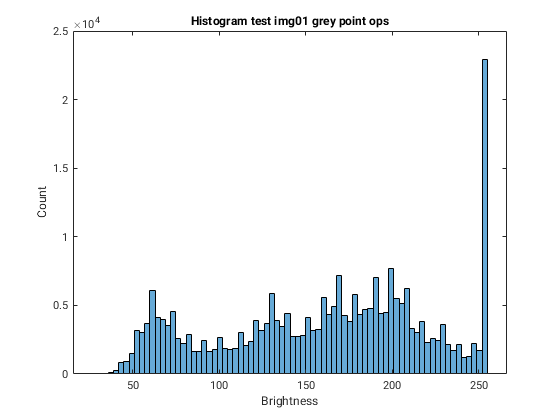

% img 01
test_img01_point_oper = a*test_img01_grey+b;
histogram(test_img01_point_oper)
xlabel('Brightness')
ylabel('Count')
title('Histogram test img01 grey point ops')

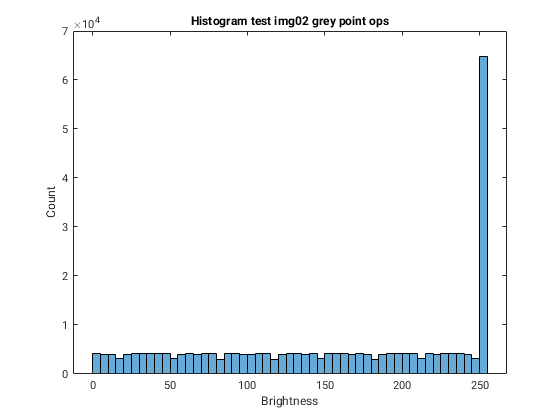

% img 02
test_img02_point_oper = a*test_img02_grey+b;
histogram(test_img02_point_oper)
xlabel('Brightness')
ylabel('Count')
title('Histogram test img02 grey point ops')

Describe your observations (in plain text) the behaviour of histogram for change in a and b values for both images:

If we increas the factor a, bright pixels get brighter very fast. Therefor we go to saturation at 355 with most of the pixels very fast in both images.

As we have some margin on the right and left side of img01, changing the factor b makes the picture brigher or darker. On img02 the same happens, but we reach the left or right border very fast. Therefore those pixels go to saturation and the bar at 255 or 0 is increasing heavily.

**Task 5** Edge detection, segmentation and boundary extraction on Images test_img 03 grey scale image. Implement your code below to seperate the characters from test_img 03 using sobel filter.

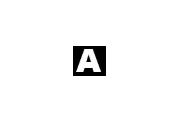

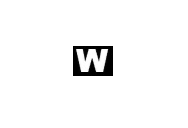

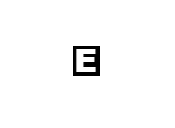

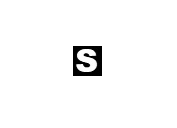

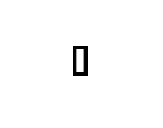

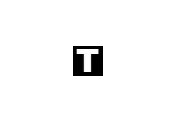

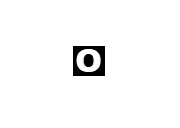

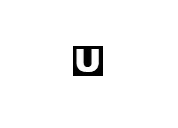

% Implement your code here

se = strel('square',10);
step1 = imdilate(test_img03_grey,se);
%imshow(step1);

[Gx,Gy] = imgradientxy(step1, 'sobel');
[Gmag,Gdir] = imgradient(Gx,Gy);
binary_03 = imbinarize(Gmag,30);
%imshow(binary_03);

WS = watershed(binary_03);

%imshowpair(WS,binary_03,'montage');
%max(WS(:))

for i = 2:max(WS(:))
    [m,n] = find(WS == i); 
    subimg = test_img03_grey(min(m):max(m), min(n):max(n));
    results{i-1} = subimg;
    figure;
    imshow(subimg)
    drawnow;
end

**Task 6** Edge detection, segmentation and boundary extraction on Images test_img 04 grey scale image.  Implement your code below to seperate the characters from test_img 04 using prewitt fiter.

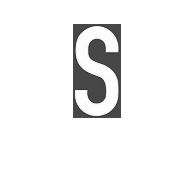

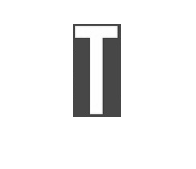

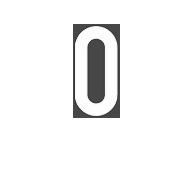

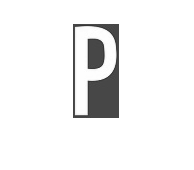

% Implement your code here

se_04 = strel('square',7);
step1 = imdilate(test_img04_grey,se_04);
%imshow(step1)

[Gx,Gy] = imgradientxy(step1, 'prewitt');
[Gmag,Gdir] = imgradient(Gx,Gy);

binary_04 = imbinarize(Gmag,30);
%imshow(binary_04);

WS_04 = watershed(binary_04);

%imshowpair(WS_04,binary_04,'montage');
%max(WS_04(:))

for i = 2:max(WS_04(:))
    [m,n] = find(WS_04 == i); 
    subimg = test_img04_grey(min(m):max(m), min(n):max(n));
    %max(m) - min(m)
    %max(n) - min(n)
    if (max(m)-min(m) > 50 && max(n)-min(n) > 10 && max(m)-min(m) < 100)
        results{i-1} = subimg;
        figure;
        imshow(subimg)
        drawnow;
    end
end